Key: 9/4/20 Thompson

1-4  see the Hagen solutions manual

Problem 5 a

clear
u=symunit;
x=7925*u.ft*u.lbf;                   %part a
x=vpa(unitConvert(x,u.kJ))

$$x = 10.74485724052634817\,\mathrm{kJ}$$

x=650*u.J/u.s;                       %part b
x=vpa(unitConvert(x,u.Btu/u.min)) 

$$x = 36.964867692219370800498616734549\,\frac{{\mathrm{Btu}}_{\mathrm{IT}}}{\min}$$

x=56*u.lbf/(u.in)^2;                 %part c
x=vpa(unitConvert(x,u.kPa))

$$x = 386.10640841742823485646971293943\,\mathrm{kPa}$$

x=25*(u.m)^3;                        %part d
x=vpa(unitConvert(x,u.gal))

$$x = 6604.3013089537103844974980402291\,\mathrm{gal}$$

x=15956*u.ft;                        %part e
x=vpa(unitConvert(x,u.km)) 

$$x = 4.8633888\,\mathrm{km}$$

x=250*u.W;                          %part f
x=vpa(unitConvert(x,u.Btu/u.h))

$$x = 853.03540828198548001150654002805\,\frac{{\mathrm{Btu}}_{\mathrm{IT}}}{h}$$

x=176*u.slug/u.min;                 %part g
x=vpa(unitConvert(x,u.kg/u.s))        

$$x = 42.808781949138670166229221347332\,\frac{\mathrm{kg}}{s}$$

x=47*u.Celsius                       %part h

$$x = 47\,\mathrm{{}^{\circ}C}$$

x=vpa(unitConvert(x,u.Rankine,'Temperature','absolute'))  %Important - the default on temperature conversions is differental

$$x = 576.27\,\mathrm{{}^{\circ}R}$$

x=1500*u.Fahrenheit        %part j dang, it's hard to spell Fahrenheit!

$$x = 1500\,\mathrm{{}^{\circ}F}$$

x=vpa(unitConvert(x,u.Celsius,'Temperature','absolute'))

$$x = 815.55555555555555555555555555556\,\mathrm{{}^{\circ}C}$$

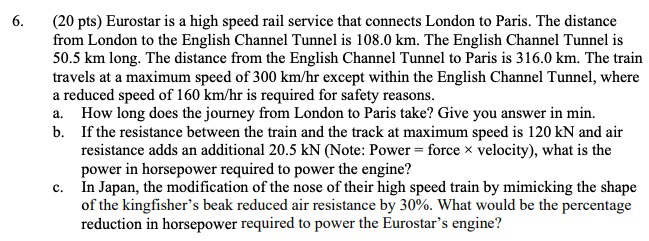

Solution:

The general equation needed is that the distance traveled is given by $d=v_{avg}T$ where $v_{avg}
$ is the average velocity and $T
$is the travel time.  Rearranging, we compute the travel time for each leg of the trip using $T=\frac{v_{avg}}{d}$ and then sum them to find the total trip time.  

clear 
u=symunit;

dLT=108*u.km; %Distance from London to Tunnel
dT=50.5*u.km; %Length of tunnel
dPT=316*u.km; %Distance from Paris to Tunnel
v0=300*u.km/u.h;
v_tunnel=160*u.km/u.hr;

ttLT=dLT/v0;    %travel time; Governing equation d=v*t: Assuming average velocity
ttT=dT/v_tunnel; 
ttPT=dPT/v0;
tt=ttLT+ttT+ttPT; %sum the three legs of travel
tt=vpa(unitConvert(tt,u.min))  %google reports estimated time of 2.5 hours - there are 16 stops.  Stops also impact average velocity. 

$$tt = 103.7375\,\min$$

tt=vpa(unitConvert(tt,u.h))

$$tt = 1.7289583333333333333333333333333\,h$$


Ft=120*u.kN+20.5*u.kN ;  %total resistant force: 

P=Ft*v0;   %Avg power at high speed
P=vpa(unitConvert(P,u.hp))

$$P = 15918.903102599879800629556743737\,{\mathrm{HP}}_{\mathrm{DIN}}$$


Ft=120*u.kN+20.5*0.7*u.kN;   %30% reduction in air resistance
PJ=Ft*v0;
PJ=vpa(unitConvert(PJ,u.hp))

$$PJ = 15222.097023731628834267480060648\,{\mathrm{HP}}_{\mathrm{DIN}}$$

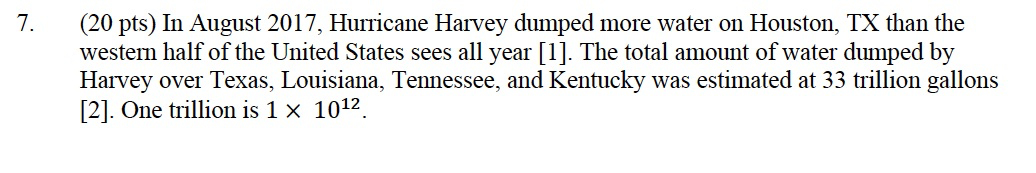

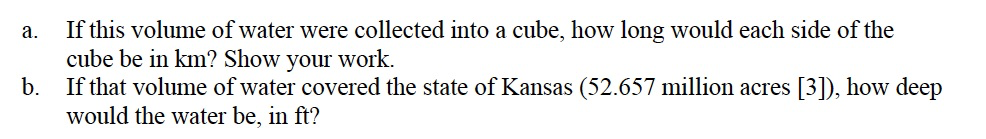

Governing equation: for a cube $V=x^3$ for a cube.  And $V=A\cdot d$ for the "depth" question. 

clear;
u=symunit;
sym x;
V=33e12*u.gal;
x=V^(1/3);
x=vpa(unitConvert(x,u.km));
x=simplify(x)

$$x = 4.9989142825539231180210457286658\,\mathrm{km}$$

x=vpa(unitConvert(x,u.mi))

$$x = 3.1061813276427681825769044583792\,\mathrm{mi}$$

A=52.657e6*u.acre;
d=V/A;           %d = depth of water in Kansas
d=vpa(unitConvert(d,u.ft))

$$d = 1.9232608798098666492232399898997\,\mathrm{ft}$$

A=669*(u.mi)^2;   % Out of curiosity...This is the size of the Houston area. If all the rain had all been on Houston - Houston acutally received 60 inches of rain. 
d=V/A;
d=vpa(unitConvert(d,u.ft))

$$d = 236.53108218457620550296185572718\,\mathrm{ft}$$